% Test jacobians
simdata = struct;
simdata.T = 0.1;
simdata.g = [0;0;1];
simdata.r = randn(3,3);
simdata.propagate_position = true;
simdata.propagate_velocity = true;
simdata.propagate_bias_alpha = true;
simdata.propagate_bias_gyro = true;
% simdata.set_T2_R_zero = true;

simdata.set_T2_R_zero = false;

Q_alpha_sqrt = randn(6,6);
simdata.Q_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;
simdata.Q_bias_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;

Q_bias_gyro_sqrt = randn(3,3);
simdata.Q_bias_gyro = Q_bias_gyro_sqrt'*Q_bias_gyro_sqrt;
% simdata.set_T2_R_zero = true;
model = D_LG_EKF_Array_v4_alpha(simdata);

R0 = expSO3(randn(3,1));
y_a = randn(3*model.N_a,1);
w0 = zeros(model.Nw,1);

% Important to check jacobian around 0 for SO(3). The jacobian is defined
% there.
% e0 = zeros(simdata.Nx,1);
e0 = [zeros(3,1); randn(model.Nx-3,1)];

f_e = @(e) model.propagate(R0*expSO3(e(1:3)),e(4:end), y_a, w0).Omega;
f_w = @(w) model.propagate(R0*expSO3(e0(1:3)),e0(4:end), y_a, w).Omega;

f_e(e0);
f_w(w0);

jac_f_e = numeric_jacobian(f_e, e0);
jac_f_w = numeric_jacobian(f_w, w0);
res = model.propagate(R0*expSO3(e0(1:3)), e0(4:end), y_a, w0);
F = res.dOmega_de;
G = res.dOmega_dw;


norm(F-jac_f_e)

ans = 1.1382e-06

norm(G-jac_f_w)

ans = 3.3193e-10

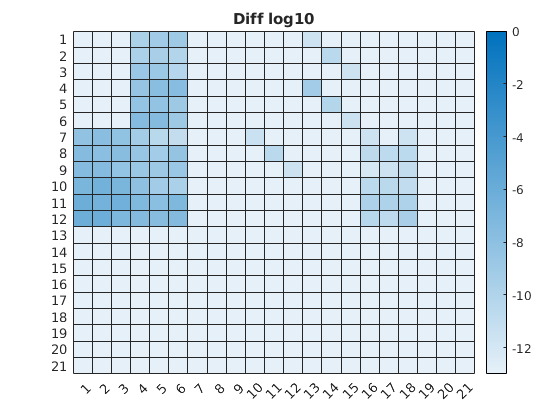


figure; 
heatmap(log10(abs(F-jac_f_e)), 'ColorLimits',[-13 0])
title("Diff log10")

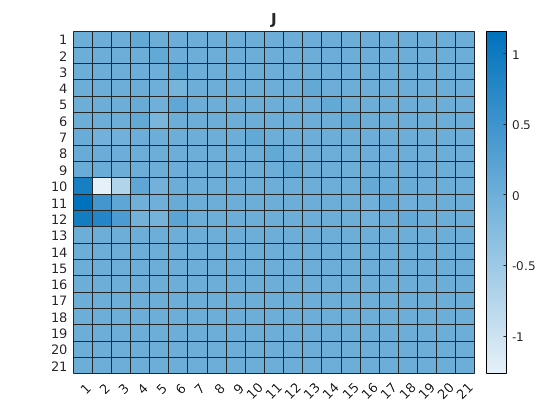

figure()
heatmap(F)
title("J")

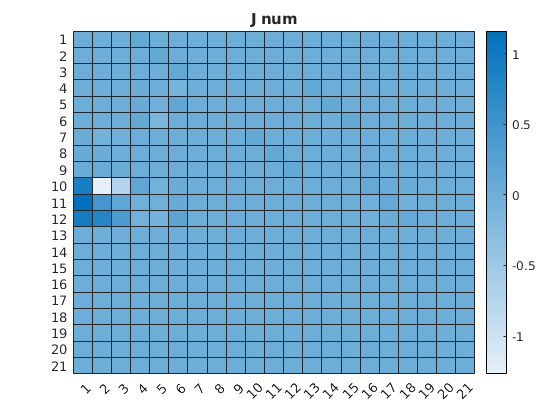

figure()
heatmap(jac_f_e)
title("J num")

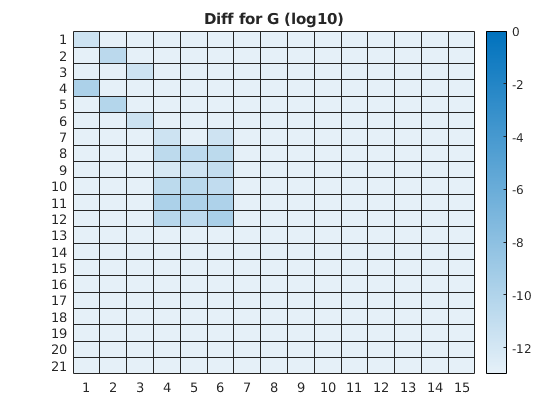

figure();
heatmap(log10(abs(G-jac_f_w)), 'ColorLimits',[-13 0])
title("Diff for G (log10)")

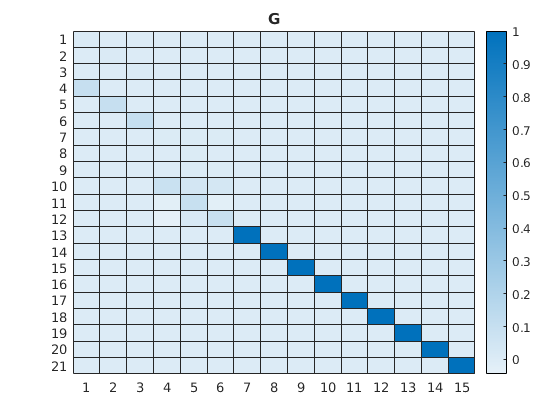


figure(5); clf
heatmap(G)
title("G")

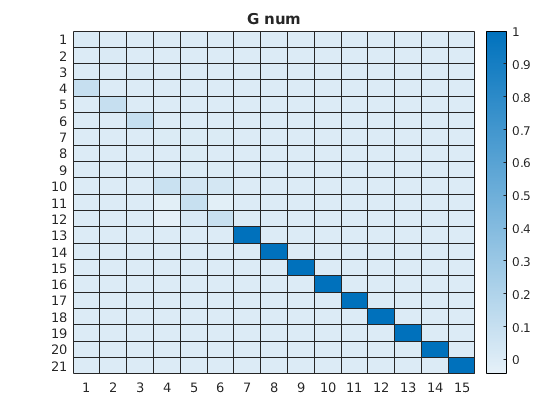

figure();
heatmap(jac_f_w)
title("G num")

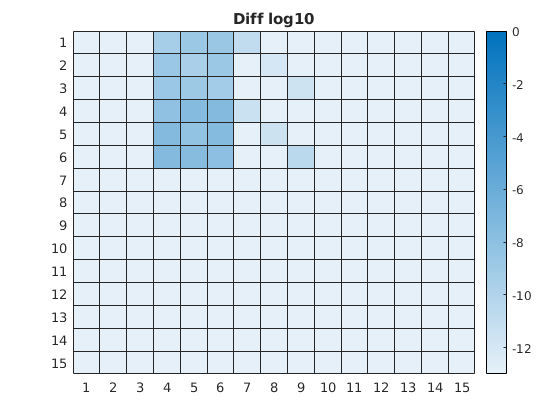

% Test jacobians
simdata = struct;
simdata.T = 0.1;
simdata.g = [0;0;1];
simdata.r = randn(3,3);
simdata.propagate_position = false;
simdata.propagate_velocity = false;
simdata.propagate_bias_alpha = true;
simdata.propagate_bias_gyro = true;

Q_alpha_sqrt = randn(6,6);
simdata.Q_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;
simdata.Q_bias_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;

Q_bias_gyro_sqrt = randn(3,3);
simdata.Q_bias_gyro = Q_bias_gyro_sqrt'*Q_bias_gyro_sqrt;
% simdata.set_T2_R_zero = true;
model = D_LG_EKF_Array_v4_alpha(simdata);

R0 = expSO3(randn(3,1));
y_a = randn(3*model.N_a,1);
w0 = zeros(model.Nw,1);

% Important to check jacobian around 0 for SO(3). The jacobian is defined
% there.
% e0 = zeros(simdata.Nx,1);
e0 = [zeros(3,1); randn(model.Nx-3,1)];

f_e = @(e) model.propagate(R0*expSO3(e(1:3)),e(4:end), y_a, w0).Omega;
f_w = @(w) model.propagate(R0*expSO3(e0(1:3)),e0(4:end), y_a, w).Omega;

f_e(e0);
f_w(w0);

jac_f_e = numeric_jacobian(f_e, e0);
jac_f_w = numeric_jacobian(f_w, w0);
res = model.propagate(R0*expSO3(e0(1:3)), e0(4:end), y_a, w0);
F = res.dOmega_de;
G = res.dOmega_dw;

figure; 
heatmap(log10(abs(F-jac_f_e)), 'ColorLimits',[-13 0])
title("Diff log10")

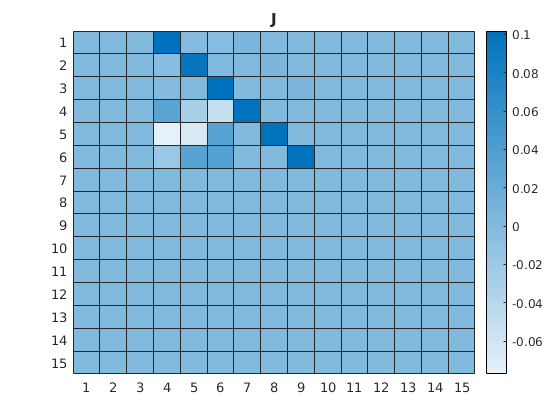

figure()
heatmap(F)
title("J")

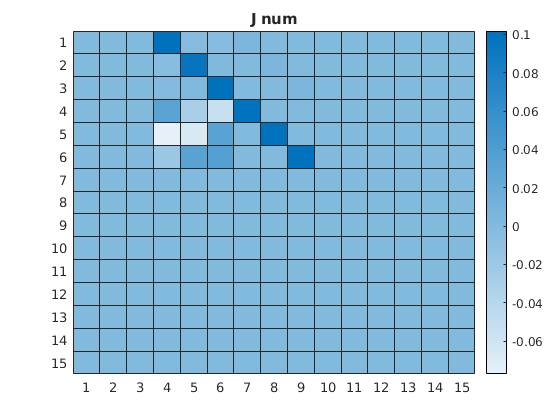

figure()
heatmap(jac_f_e)
title("J num")

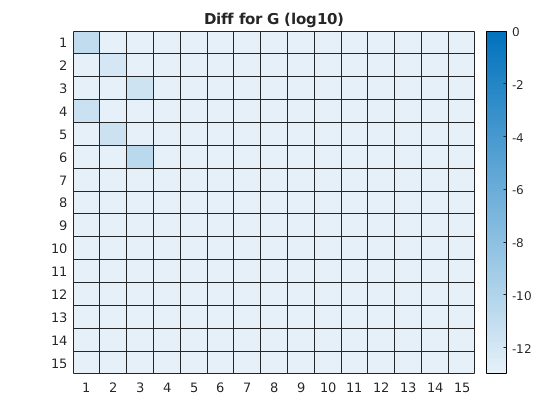

figure();
heatmap(log10(abs(G-jac_f_w)), 'ColorLimits',[-13 0])
title("Diff for G (log10)")

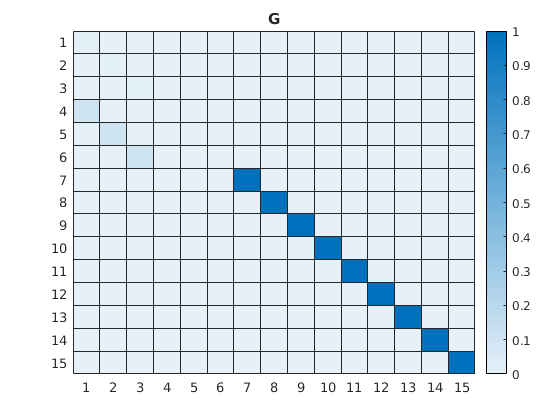


figure(5); clf
heatmap(G)
title("G")

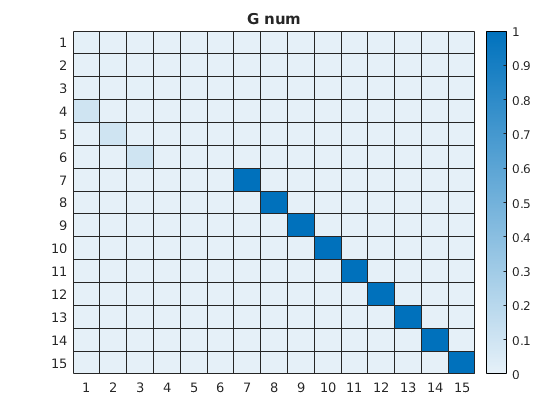

figure();
heatmap(jac_f_w)
title("G num")


norm(F-jac_f_e)

ans = 6.5982e-08

norm(G-jac_f_w)

ans = 2.5019e-11

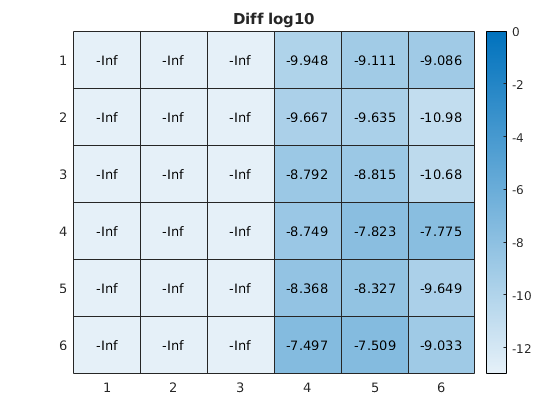

% Test jacobians
simdata = struct;
simdata.T = 0.1;
simdata.g = [0;0;1];
simdata.r = randn(3,3);
simdata.propagate_position = false;
simdata.propagate_velocity = false;
simdata.propagate_bias_alpha = false;
simdata.propagate_bias_gyro = false;

Q_alpha_sqrt = randn(6,6);
simdata.Q_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;
simdata.Q_bias_alpha = Q_alpha_sqrt'*Q_alpha_sqrt;

Q_bias_gyro_sqrt = randn(3,3);
simdata.Q_bias_gyro = Q_bias_gyro_sqrt'*Q_bias_gyro_sqrt;
% simdata.set_T2_R_zero = true;
model = D_LG_EKF_Array_v4_alpha(simdata);

R0 = expSO3(randn(3,1));
y_a = randn(3*model.N_a,1);
w0 = zeros(model.Nw,1);

% Important to check jacobian around 0 for SO(3). The jacobian is defined
% there.
% e0 = zeros(simdata.Nx,1);
e0 = [zeros(3,1); randn(model.Nx-3,1)];

f_e = @(e) model.propagate(R0*expSO3(e(1:3)),e(4:end), y_a, w0).Omega;
f_w = @(w) model.propagate(R0*expSO3(e0(1:3)),e0(4:end), y_a, w).Omega;

f_e(e0);
f_w(w0);

jac_f_e = numeric_jacobian(f_e, e0);
jac_f_w = numeric_jacobian(f_w, w0);
res = model.propagate(R0*expSO3(e0(1:3)), e0(4:end), y_a, w0);
F = res.dOmega_de;
G = res.dOmega_dw;

figure; 
heatmap(log10(abs(F-jac_f_e)), 'ColorLimits',[-13 0])
title("Diff log10")

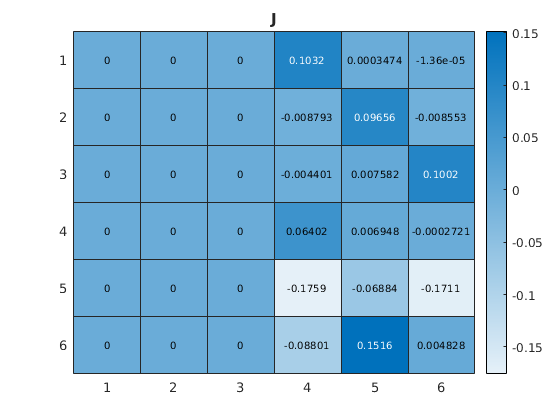

figure()
heatmap(F)
title("J")

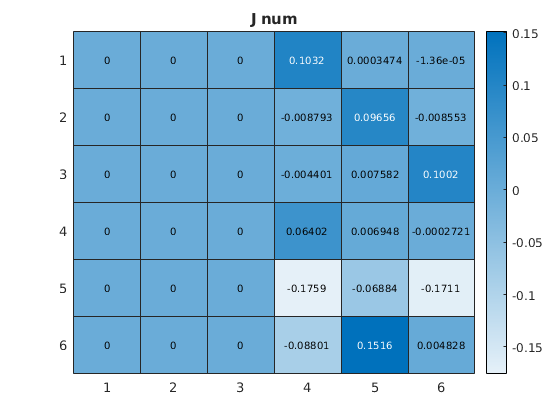

figure()
heatmap(jac_f_e)
title("J num")

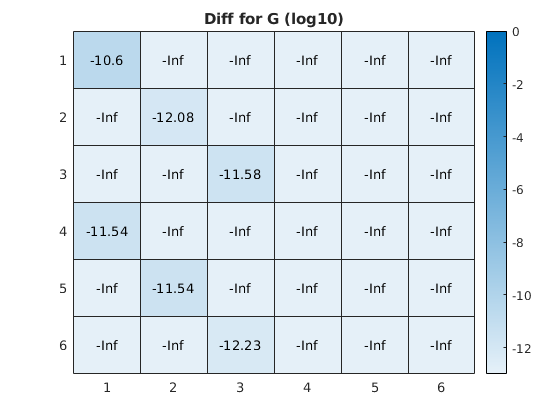

figure();
heatmap(log10(abs(G-jac_f_w)), 'ColorLimits',[-13 0])
title("Diff for G (log10)")

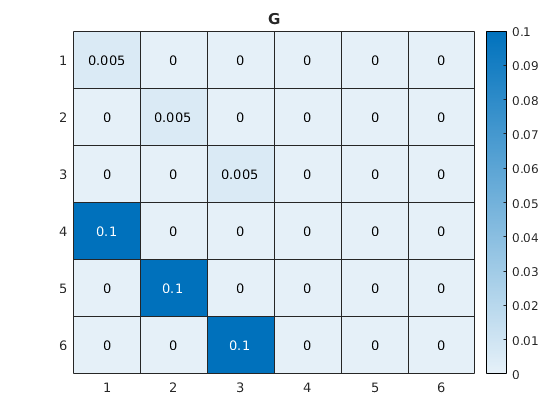


figure(5); clf
heatmap(G)
title("G")

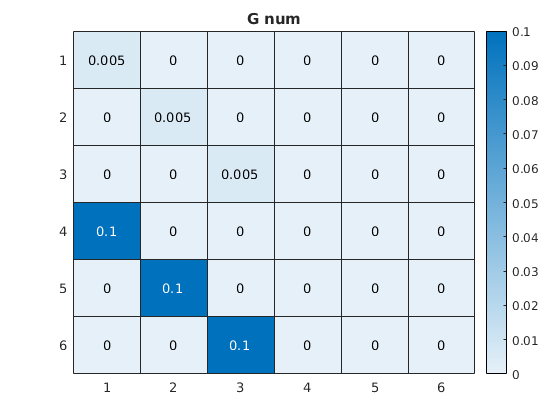

figure();
heatmap(jac_f_w)
title("G num")


norm(F-jac_f_e)

ans = 4.6014e-08

norm(G-jac_f_w)

ans = 2.5288e-11